Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Dispersion integral for Gaussian momentum distributions (Section 12.4)

Volker Ziemann, 211124, CC-BY-SA-4.0

**Important:** requires the Faddeeva package from [https://www.mathworks.com/matlabcentral/fileexchange/38787-faddeeva-package-complex-error-functions](https://www.mathworks.com/matlabcentral/fileexchange/38787-faddeeva-package-complex-error-functions).

The stability of un-bunched or coasting beams with momentum distribution $\psi_0(\delta)$is determined by the dispersion integral $I_D(\Omega)$ from Equation 12.17. For a Gaussian distribution $\psi_0(\delta)$ it can be solved in closed form as given in Equation 12.19 and which we simply code as a function `ID(xi1)`, where `xi1` is the scaled frequency $\Omega$ as defined in Equation 12.19.. Since it depends on the complex error function $w(z)$ we load the Faddeeva package. 

clear 
addpath ./Faddeeva/
ID=@(xi1)1+1i*sqrt(pi/2).*xi1.*Faddeeva_w(xi1/sqrt(2));  % eq. 12.19

Now we specify the real and imaginary part of possible frequencies $\Omega$, where a positive imaginary part descibes a damped and stable oscillation mode. Conversely, a negative imaginary part leads to an unstable and exponentially growing mode. 

xi1=-3.3:0.1:3.3;      % range of scaled 'frequencies', see eq. 12.19

The limit between stable and unstable modes is thus defined by a purely real frequency $\Omega$ or its scaled version $\xi_1$, which is defined in Equation 12.19. We therefore calculate the dispersion integral for real frequencies first. The real and imaginary part of $U+iV\propto I_0(Z_{||}/n)$ are proportional to the product of beam current $I_0$ and longitudinal impedance $Z_{||}/n$. They are also related to the dispersion integral by $U+iV=i/I_D(\Omega)$, which we immediately determine. Plotting $V$ versus $U$ then separates the complex and scaled impedance plane into a stable and an unstable region. 

z=ID(xi1); 
U=real(1i./z); 
V=imag(1i./z);

In order to probe whether the inside is stable or unstable we add an imaginary part to $\xi_1$, calcuillate the corresponding dispersion integral, and calculate the points $U +i V$ in the impedance plane.

damp=0.03 % Slider to set imaginary part

damp = 0.0300

xi2=xi1-1i*damp;       % Im(Omega)>0 --> Im(xi1)<0
z=ID(xi2); 
U2=real(1i./z); 
V2=imag(1i./z);

Finally, we plot $U+iV$ for the case without damping as a black line and with damping added as a blue dahed line. We also add the Keil-Schell circle as a red dotted curve, whose inside provides a conservative estimate for stability, because if  $U+iV\propto I_0(Z_{||}/n)$ are inside this circle the beams also lie inside the black curve, which separates the stable from the unstable region.

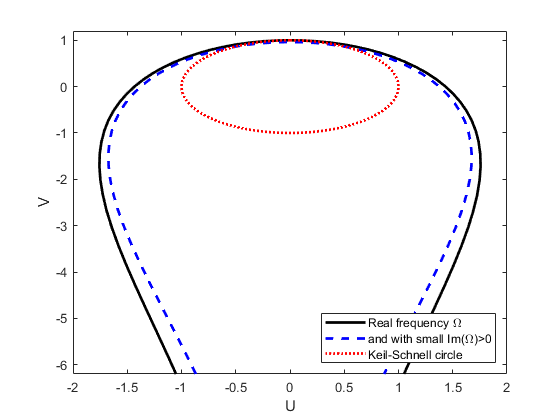

phi=0:2*pi/100:2*pi;   % for Keil-Schnell circle
plot(U,V,'k',U2,V2,'b--',sin(phi),cos(phi),'r:','LineWidth',2)
xlabel('U'); ylabel('V');
legend('Real frequency \Omega','and with small Im(\Omega)>0', ...
  'Keil-Schnell circle','Location','SouthEast')
ylim([-6.2,1.2])

And now play with the slider to set the imaginary part of $\xi_1$ and see how negative values put all blue points on the outside of the black line.